
close all
clear all
colors=npg(10); % Ten basic colors 
tpi = 2*pi;
gamma171 = 7.50e6;   % freq, Hz/T
gamma173 = 2.07e6*5;

% near %
maindir='\\Artemis-pc\Data\2026-04-21\Abs-516\';   % 靠近，对比度
load([maindir,'\FitResult.mat']);

a171n = amp2+0*a_sigma2;   % 171 对比度
a171n_sigma = a_sigma2;
T171n = T2;
a173n = amp+2*a_sigma;   % 173 对比度
a173n_sigma = a_sigma;
T173n = T;

% far %
maindir='\\Artemis-pc\Data\2026-04-21\Abs-516\';   % 远离，对比度
load([maindir,'\FitResult.mat']);

a171f = amp2+0*a_sigma2;   % 171 对比度
a171f_sigma = a_sigma2;
T171f = T2;
a173f = amp+2*a_sigma;   % 173 对比度
a173f_sigma = a_sigma;
T173f = T;

maindir='\\Artemis-pc\Data\2026-04-21\Abs-670\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);



% ！！注意修改 周期数 和 进动时间 ！！ %

tau_s = 6;   % s，不包含旋转位移台时间
tau_ms_n = 78;   % ms,near
tau_ms_f = 78;   % ms,far
coefficient171 = +1;
coefficient173 = -1;

wait1 = 9.3;   % ms
wait2 = 46;   % ms

ROT_list = -[1 -1 -1 1 -1 1 1 -1];   % 旋转序列，靠近(1)，远离(-1)
ROTlen = length(ROT_list);
for k = 1:ROTlen
    % 靠近 %
    if ROT_list(k) == 1
        a171(k) = a171n;
        a171_sigma(k) = a171n_sigma;
        T171(k) = T171n;
        a173(k) = a173n;
        a173_sigma(k) = a173n_sigma;
        T173(k) = T173n;
        tau_ms(k) = tau_ms_n;
    % 远离 %
    elseif ROT_list(k) == -1
        a171(k) = a171f;
        a171_sigma(k) = a171f_sigma;
        T171(k) = T171f;
        a173(k) = a173f;
        a173_sigma(k) = a173f_sigma;
        T173(k) = T173f;
        tau_ms(k) = tau_ms_f;
    end
end


% 进动时间，秒数在第一段修改 %
precession = tau_s*1e3 + tau_ms;   % 时序可设置的进动时间
precession_total = (tau_s+2*2)*1e3 + tau_ms;   % 包括转台转动时间，前后各2s

tau171 = precession_total+(4+wait1)+(4+wait2)*3;
N171 = floor(tau171./T171)+2;
tau173 = precession_total+(4+wait1);
N173 = floor(tau173./T173(1))+1;



% 不考虑进动曲线 Offset 
diff_n = floor(length(s1)/ROTlen);
for k = 1:diff_n
    temp = (k-1)*ROTlen+1:k*ROTlen;
    % 171总相位 %
    dphase171(temp) = ...
        real(asin(((s3(temp)-s4(temp))./(s3(temp)+s4(temp)))'./a171));
    p171(temp) = (N171)*tpi + coefficient171*dphase171(temp);
    f171(temp) = p171(temp)./(tau171*1e-3)/tpi;   % frequency Hz
    % 173总相位 %
    dphase173(temp) = ...
        real(asin(((s1(temp)-s2(temp))./(s1(temp)+s2(temp)))'./a173));
    p173(temp) = N173*tpi + coefficient173*dphase173(temp);
    f173(temp) = p173(temp)./(tau173*1e-3)/tpi;   % frequency Hz
end

% 171总相位 %
pm171 = mean(p171);
fm171 = mean(f171);

% 173总相位 %
pm173 = mean(p173);
fm173 = mean(f173);

% 频率比 %
rf = f171./f173;
% 相位比 %
rp = p171./p173;
rpm=mean(rp)

rpm = 0.7406

rpstd=std(rp)/sqrt(length(rp)-1)

rpstd = 1.0576e-05

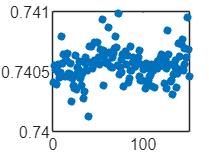

figure
plot(1:length(rp),rp,'.','MarkerSize',12);

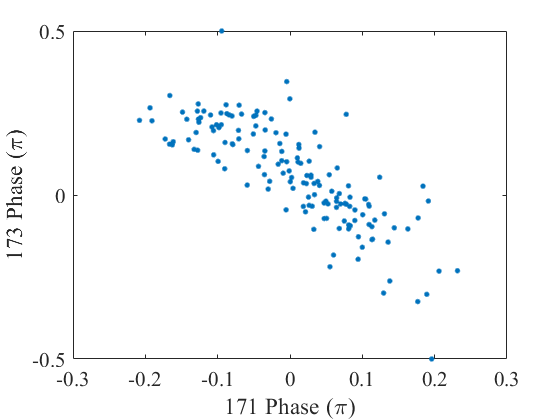

% 相位关联 %
f0 = figure;
plot(dphase171/pi,dphase173/pi,'.','MarkerSize',12);
xlabel('171 Phase (\pi)');
ylabel('173 Phase (\pi)');
grid off;
box on;

set(f0,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

## 差分相位


ROTlen = length(ROT_list);
diff_n = floor(length(rp)/ROTlen);
for k = 1:diff_n
    templist = (k-1)*ROTlen+1:k*ROTlen;
    temp = rp(templist);
    diff_rp(k) = (ROT_list*temp')/(ROTlen/2);

    % 频率比 %
    temp = rf(templist);
    diff_rf(k) = (ROT_list*temp')/(ROTlen/2);

    % 有效进动时间内,171累积的频率差 %
    temp = p171(templist);
    df171(k) = (ROT_list*(temp./precession*1e3)')/(ROTlen/2)/tpi;   % Hz
    % 有效进动时间内,173累积的频率差 %
    temp = p173(templist);
    df173(k) = (ROT_list*(temp./precession*1e3)')/(ROTlen/2)/tpi;   % Hz
end

dp = diff_rp*pm173;
dpm = mean(dp);
dps = std(dp)/sqrt(diff_n-1);
df = dp*precession(1);   % Hz
dfm = mean(df);
dfs = std(df)/sqrt(diff_n-1);

dB171 = df171/gamma171*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm171 = mean(dB171);
dBs171 = std(dB171)/sqrt(diff_n-1);

dB173 = df173/gamma173*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm173 = mean(dB173);
dBs173 = std(dB173)/sqrt(diff_n-1);

% 差分频率比 %
drpm = mean(diff_rp);
drps = std(diff_rp)/sqrt(diff_n-1);
drfm = mean(diff_rf);
drfs = std(diff_rf)/sqrt(diff_n-1);


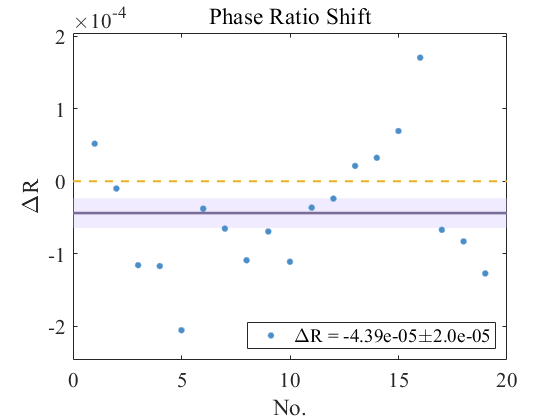


f1 = figure; hold on;

xmin = 0;
xman = diff_n+1;
ymin = min([-abs(drpm*0.2) min(diff_rp)*0.8 min(diff_rp)*1.2]);
ymax = max([abs(drpm*0.2) max(diff_rp)*0.8 max(diff_rp)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 drpm-drps ; diff_n+1 drpm-drps ; ...
    diff_n+1 drpm+drps ; 0 drpm+drps];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xman],[drpm drpm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],diff_rp,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaR');
title('Phase Ratio Shift');
legend('','',['\DeltaR = ',num2str(drpm,'%.2e'),'\pm',num2str(drps,'%.1e')],'',...
    'Location','southeast');
grid off;
box on;

set(f1,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

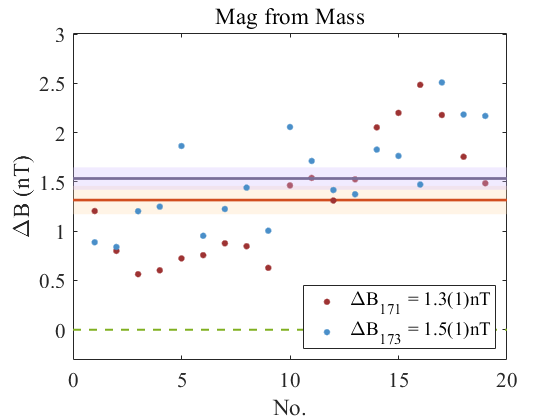


f11 = figure; hold on;
xmin = 0;
xman = diff_n+1;
ymin = min([-abs([dBm171 dBm173]*0.2) min([dB171,dB173])*0.8 min([dB171,dB173])*1.2]);
ymax = max([abs([dBm171 dBm173]*0.2) max([dB171,dB173])*0.8 max([dB171,dB173])*1.2]);

% 171测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm171-dBs171 ; diff_n+1 dBm171-dBs171 ; ...
    diff_n+1 dBm171+dBs171 ; 0 dBm171+dBs171];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[1 0.85 0.67],'EdgeColor','none');
l11 = plot([0 xman],[dBm171 dBm171],Color=[0.82 0.3 0.12],LineWidth=2);

l12 = plot([1:diff_n],dB171,'.','MarkerSize',15);
l12.Color = [0.62,0.2,0.2];


% 173测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm173-dBs173 ; diff_n+1 dBm173-dBs173 ; ...
    diff_n+1 dBm173+dBs173 ; 0 dBm173+dBs173];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l21 = plot([0 xman],[dBm173 dBm173],Color=[0.48 0.43 0.60],LineWidth=2);

l22 = plot([1:diff_n],dB173,'.','MarkerSize',15);
l22.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.5 0.69 0.13]);


if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaB (nT)');
title('Mag from Mass');
legend('','',['\DeltaB_{171} = ',num2str(dBm171,'%.1f'),'(',num2str(dBs171*1e1,'%.0f'),')nT'],...
    '','',['\DeltaB_{173} = ',num2str(dBm173,'%.1f'),'(',num2str(dBs173*1e1,'%.0f'),')nT'],'',...
    'Location','southeast');
grid off;
box on;

set(f11,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

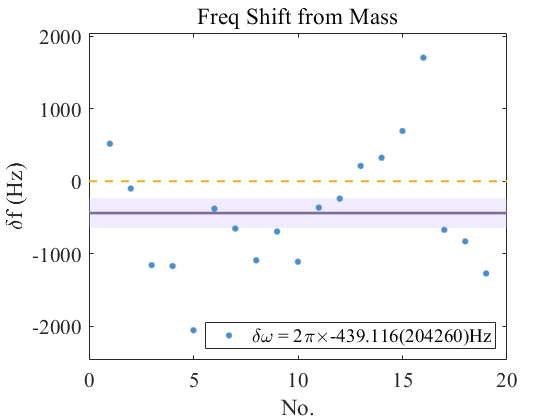


f2 = figure; hold on;

xmin = 0;
xman = diff_n+1;
ymin = min([-abs(dfm*0.2) min(df)*0.8 min(df)*1.2]);
ymax = max([abs(dfm*0.2) max(df)*0.8 max(df)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 dfm-dfs ; diff_n+1 dfm-dfs ; diff_n+1 dfm+dfs ; 0 dfm+dfs];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xman],[dfm dfm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],df,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\deltaf (Hz)');
title('Freq Shift from Mass');
legend('','',['\delta\omega = 2\pi\times',num2str(dfm,'%.3f'),'(',num2str(dfs*1e3,'%.0f'),')Hz'],'',...
    'Location','southeast');
grid off;
box on;

set(f2,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');


savefig(f0,[main_dir_0,'cophase.fig']);
saveas(f0,[main_dir_0,'cophase.png']);

savefig(f1,[main_dir_0,'dRf.fig']);
saveas(f1,[main_dir_0,'dRf.png']);

savefig(f11,[main_dir_0,'dB.fig']);
saveas(f11,[main_dir_0,'dB.png']);

savefig(f2,[main_dir_0,'df.fig']);
saveas(f2,[main_dir_0,'df.png']);


save([main_dir_0,'diffR.mat']);